addpath("helperFunctions/");
clearvars;

# Plane Wave

$\theta$ is the elevation angle from $0$ to $\pi$

$\phi$ is the azimuth angle from $0$ to $2\pi$


$$\rho = \sqrt{(x^2+y^2+z^2)}$$



$$\theta = tan^{-1}\bigg(\frac{\sqrt{x^2+y^2}}{z}\bigg)$$



$$\phi = atan2\bigg(y,x\bigg) = tan^{-1}\bigg(\frac{y}{x}\bigg),\quad  x >0$$



$$x = \rho\sin\theta\cos\phi$$



$$y = \rho\sin\theta\sin\phi$$



$$z = \rho\cos\theta$$


#### Plane wave - Expansion in Spherical Harmonics

According to [https://en.wikipedia.org/wiki/Plane-wave_expansion](https://en.wikipedia.org/wiki/Plane-wave_expansion) as plane wave can be expressed as a linear combination of spherical harmonics:


$$e^{i\mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(kr)\overline Y_{lm}(\mathbf \hat k){Y}_{lm}(\mathbf \hat r),$$


where

$\overline Y_{lm} = (-1)^mY_{l,-m}$ is the complex conjugate matrix,

$i$ is the imaginary unit,

$\mathbf k$ is a wave vector of length $k$,

$\mathbf r$ is a position vector of length $r$,

$\mathbf \hat k = \frac{\mathbf k}{|\mathbf k|}$ and $\mathbf \hat r$ is the unit vector of $\mathbf k$ and $\mathbf r$ respectively.

in spherical coordinates  $\mathbf k\{\rho_k,\theta_k,\phi_k\}$ and  $\mathbf r\{\rho_r,\theta_r,\phi_r\}$.


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r),$$


where 


$$\mathbf k \cdot \mathbf r = \rho_k\rho_r[\sin\theta_k\sin\theta_r\cos(\phi_k-\phi_2)+\cos\theta_k\cos\theta_r]$$


$\rho_k = \frac{2\pi}{\lambda} = \frac{2\pi f}{c}$,

$\lambda$ is the wave length

## 1D Plane Wave Expansion - Legendre - Harmonics

### Initial Parameters

clearvars
n = 3; spacing = 0.1;
f = 200; c = 343; omega = 2*pi*f;
k = [omega/c;0;0];

rx = -n:spacing:n;
ry = 5; rz = 10;
sz = [length(ry) length(rx)];
r = [rx;ones(sz)*ry;ones(sz)*rz];
R = 0.5; %region of interrest
L = ceil(exp(1)*k(1)*R/2);

### Wave in Exponent Form

figure;
subplot(311);
wave = expWave(sz,r,k,1,1);

### Plane Wave Expansion - Legendre


$$e^{i\mathbf k \cdot \mathbf r} = \sum_{l=0}^\infty (2l+1)i^lj_l(kr)P_l(\hat \mathbf k \cdot\hat\mathbf r)$$


subplot(312);
P = legendreWave(L,r,k,1);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


#### Compare

cmpWaves(P,wave,0);

ans = "Max real error:  1.02e+00"

ans = "Max imag error:  1.01e+00"

ans = "Mean error: 6.36e-01"

### Plane Wave Expansion - Harmonics


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)Y_{lm}(\theta_k,\phi_k)\overline{Y}_{lm}(\theta_r,\phi_r),$$
 

or


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r),$$


### Harmonic Matrix - $Y_{lm}(\theta_k,\phi_k)$

[rho_k,the_k,phi_k] = my_cart2sph(k);
[rho_r,the_r,phi_r] = my_cart2sph(r);
L = ceil(exp(1)*rho_k*max(rho_r));
Yk = harmonicMatrix(L,the_k,phi_k);
cYk = conj(Yk);

### 1 - $\overline{Y}_{lm}(\theta_r,\phi_r)$

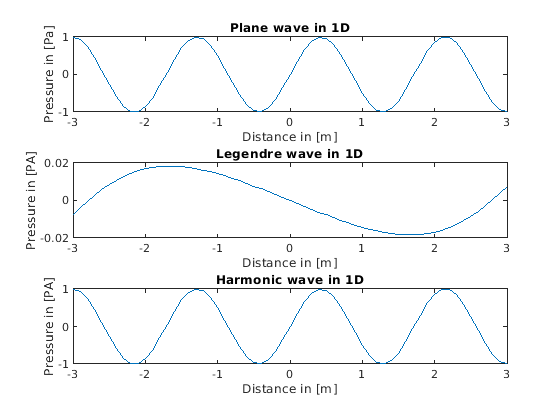

subplot(313);
P = harmonicWave(L,r,k,1);

cmpWaves(P,wave,0);

ans = "Max real error:  1.15e-14"

ans = "Max imag error:  6.05e-15"

ans = "Mean error: 2.65e-15"

## 2 Dimensions

### Initial Parameters

clearvars
n = 3; spacing = 0.01;
f = 200; c = 343; omega = 2*pi*f;
rho_k = omega/c;
phi_k = pi;
the_k = pi/2;
k = my_sph2cart(the_k,phi_k,rho_k);
rx = -n:spacing:n;
ry = rx;
sz = [length(ry),length(rx)];
rz = ones(1,sz(1))*0;
r = [rx;ry;rz];
R = 0.5; % region of interrest
L = ceil(exp(1)*rho_k*R/2);

### 2D Plane Wave - Exponent Form

figure;
wave = expWave(sz,r,k,2,1);

### 2D Plane Wave Expansion - Legendre

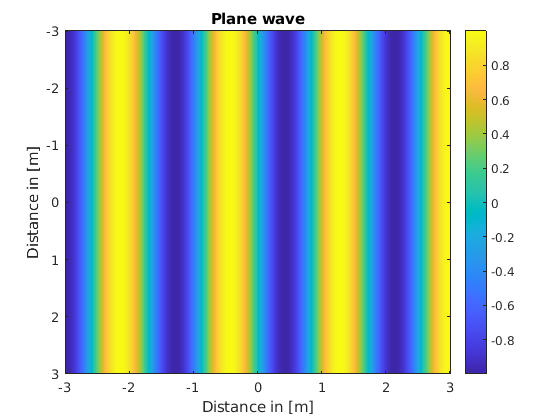

Pl = zeros(sz);
h = waitbar(0,'init');

for idy = 1:sz(1)
    waitbar(idy/sz(1),h,"load");
    rInter = [r(1,:);ones(1,sz(2))*r(2,idy);r(3,:)];
    Pl(idy,:) = legendreWave(L,rInter,k,0);
end
close(h);
figure;
imagesc(imag(Pl)); colorbar;
title("Legendre Wave");

### Compare

cmpWaves(Pl,wave,1)

ans = "Max real error:  1.24e+00"

ans = "Max imag error:  1.19e+00"

ans = "Mean error: 5.17e-01"

ans = 0.5167

sgtitle("Legendre Error");

### 2D Plane Wave Expansion - Harmonic

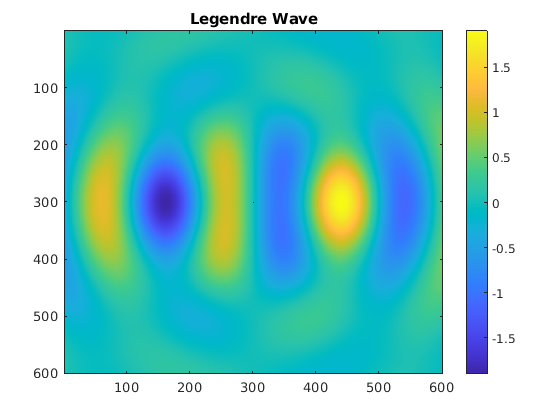

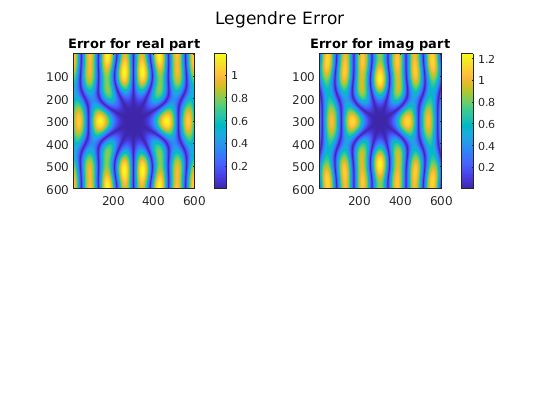

Ph = zeros(sz);
h = waitbar(0,'init');
for idy = 1:sz(1)
    waitbar(idy/sz(1),h,"load");
    rInter = [r(1,:);ones(1,sz(2))*r(2,idy);r(3,:)];
    Ph(idy,:) = harmonicWave(L,rInter,k,0);
end

figure;
close(h);
imagesc(imag(Ph)); colorbar;
title("Harmonic Wave");

### Compare

cmpWaves(Ph,wave,1)

ans = "Max real error:  1.24e+00"

ans = "Max imag error:  1.19e+00"

ans = "Mean error: 5.17e-01"

ans = 0.5167

sgtitle("Harmonic Error");
sprintf("Compare in region of interrest")

ans = "Compare in region of interrest"

interval1 = floor(sz(1)/2-R/spacing):ceil(sz(1)/2+R/spacing);
interval2 = floor(sz(2)/2-R/spacing):ceil(sz(2)/2+R/spacing);
cmpWaves(wave(interval1,interval2),Ph(interval1,interval1),1);

ans = "Max real error:  1.32e-01"

ans = "Max imag error:  3.96e-02"

ans = "Mean error: 1.26e-02"

### Plane Wave - Harmonic Coefficients

We have seen previously that a plane wave can be expressed as a linear combination of spherical harmonics as


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)Y_{lm}(\theta_k,\phi_k)\overline{Y}_{lm}(\theta_r,\phi_r),$$


Due to symetrie the complex conjugation is interchangeable therefore


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r),$$


and


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


therefore for a plane wave


$$4\pi i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r) = C_{lm}(k)j_l(kr)Y_{lm}(\theta_r,\phi_r)$$



$$\Leftrightarrow C_{lm}(k) = 4\pi i^l  \overline Y_{lm}(\theta_k,\phi_k)\frac{{Y}_{lm}(\theta_r,\phi_r) }{Y_{lm}(\theta_r,\phi_r)}$$



$$\Leftrightarrow C_{lm}(k) = 4\pi i^l  \overline Y_{lm}(\theta_k,\phi_k)$$


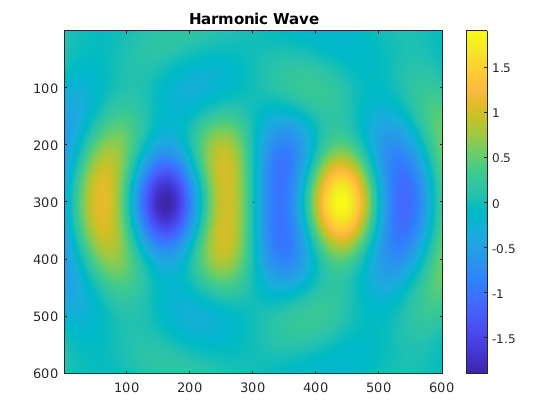

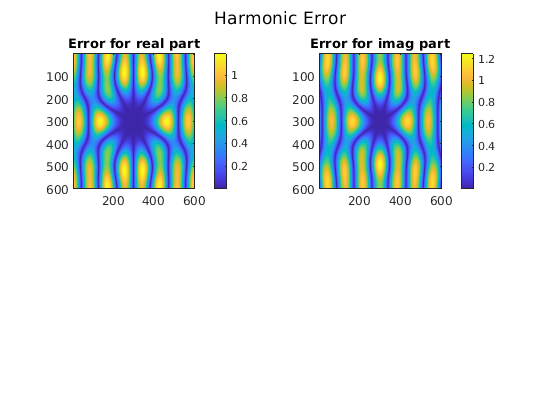

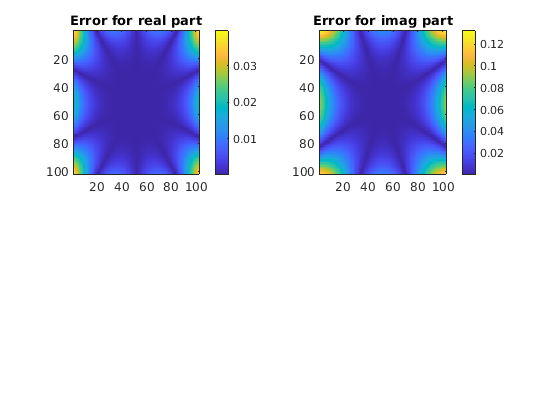

Yk = harmonicMatrix(L,the_k,phi_k);
Clm = 4.*pi.*1i.^((0:L).').*conj(Yk);
P = harmonics2pressure(Clm,rho_k,r,sz);

figure;
imagesc(imag(P));
title("Plane Wave - Harmonic Coefficients");

### Compare

cmpWaves(Ph,wave,1)

ans = "Max real error:  1.24e+00"

ans = "Max imag error:  1.19e+00"

ans = "Mean error: 5.17e-01"

ans = 0.5167

sgtitle("Harmonic Coefficient Error");

## Harmonic Coefficients

We have 


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


By multiplying both side by $\overline\mathbf{Y}_{lm}$ and integrating over the sphere we get:


$$C_{lm}(k) = \frac{1}{\mathbf j_l(kr)}\int_0^\pi\int_0^{2\pi}P(r,\theta,\phi,k)\overline\mathbf{Y}_{lm}(\theta,\phi)d\theta d\phi$$


where 

$\overline\mathbf{Y}_{lm}$ is the complex conjugate matrix of $\mathbf{Y}_{lm}$

### Harmonic Coefficients - Numerical Integration - Matlab

n = 1000;
a1 = 0;  a2 = 0;
b1 = pi; b2 = 2*pi;
Clm2 = zeros(L+1,2*L+1);


for l=0:L
    idl = l+1;
    for m=-l:l
        idm = m+idl;
        fun = @(the,phi) exp(1i.*myDot(rho_k,the_k,phi_k,R,the,phi)).*cYlm(l,m,the,phi)./sphbessel(l,rho_k*R);
        Clm2(idl,idm) = integral2(fun,a1,b1,a2,b2);
    end
end

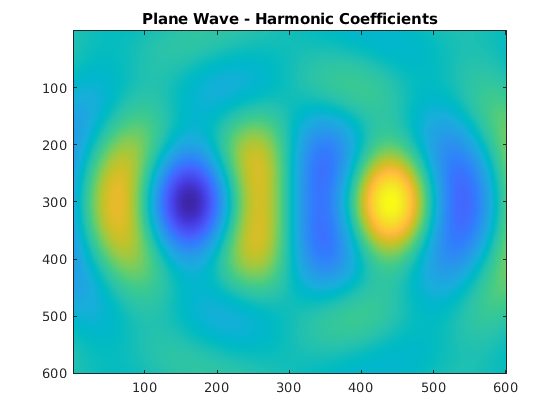

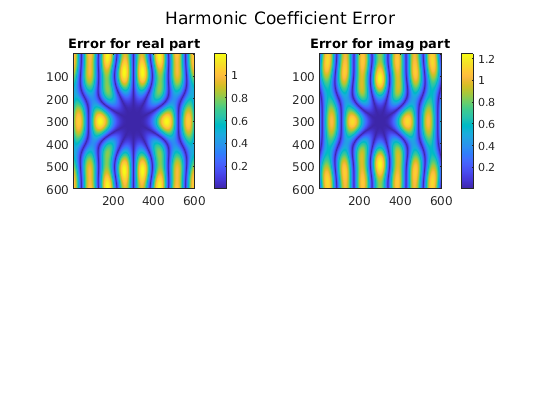

P2 = harmonics2pressure(Clm2,rho_k,r,sz);

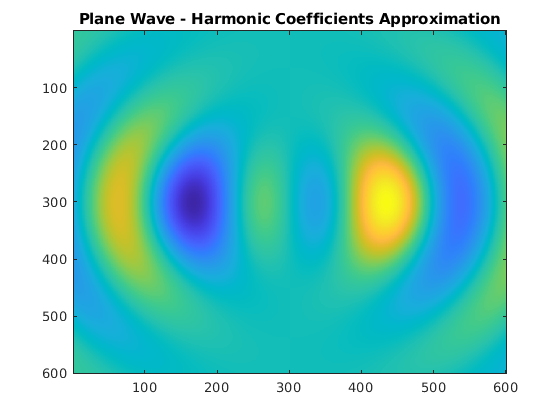

figure;
imagesc(imag(P2));
title("Plane Wave - Harmonic Coefficients Approximation");

### Compare

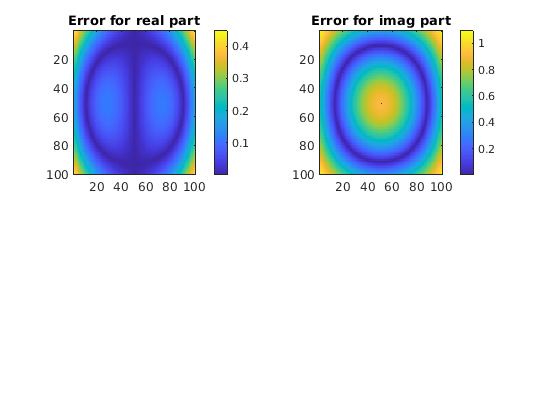

ans = "Max real error:  1.09e+00"

ans = "Max imag error:  4.48e-01"

ans = "Mean error: 2.50e-01"

interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);
cmpWaves(wave(interval1,interval2),P2(interval1,interval1),1);

### Harmonic Coefficient - Spherical Microphone array

$C_{lm}(k) = \frac{1}{j_l(kR)}\sum_iP(R,\theta_i,\phi_i,k)\overline Y_{lm}(\theta_i,\phi_i)\gamma_i$,

where

$\theta_i$ and $\phi_i$ are the elevation and azimuth of the $i$th microphone,

$\gamma_i$ are some weighting coefficients specific to the sampling scheme of the microphone array.

### Numerical Integration - Gauss-Legendre Quadrature on the sphere

According to "The fundamentals of Spherical Array Processing by Boaz Rafaely"

A function $f(\theta, \phi) \in L_2(S^2)$ can be represented using a weighted sum of spherical harmonics as


$$f(\theta,\phi) = \sum_{n=0}^\infty \sum_{m=-n}^n f_{nm}Y_n^m(\theta,\phi),$$


where $f_{nm}$ are the weigths. These weigths form the spherical Fourier transform of $f(\theta,\phi)$ and can be derived from $f(\theta,\phi)$ by


$$f_{nm} = \int_0^{2\pi}\int_0^{\pi}f(\theta,\phi)\overline Y_{n}^m(\theta,\phi)\sin\theta\,d\theta\,d\phi.$$


#### Gaussian Sampling

The spherical Fourier transform can be sampled using the gaussian sampling scheme and is given by


$$f_{nm} = \sum_{q=0}^N\sum_{l=0}^{2N+1}a_qf(\theta_q,\phi_l)\overline Y_n^m(\theta_q,\phi_l), \quad n \leq N.$$


When applying this on the harmonic coefficients we get


$$C_{lm}(k) = \frac{1}{j_l(kR)} \sum_{q=0}^N\sum_{p=0}^{2N+1}a_qP(R,\theta_q,\phi_p,k)\overline Y_{lm}(\theta_q,\phi_p)$$


where the weights are given by


$$a_q = \frac{\pi}{N+1}\frac{2(1-\cos^2\theta_q)}{(N+2)^2[P_{N+2}(\cos \theta_q)]^2}, \quad 0 \leq q\leq N$$


where the azimuth angle is sampled at $2(N+1)$ equal-angle samples:


$$\phi_p = p\frac{2\pi}{2N+2},\quad p=0,...,2N+1$$


The elevation angle is sampled by selecting $(N+1)$ samples that are the zeros of $P_{N+1}(\cos\theta)$,


$$P_{N+1}(\cos\theta_q)=0, \quad 0 \leq q \leq N$$


where 

$P_{N+1}$ is the legendre polynomial of degree $N+1$

which means a total number of samples/microphone of $2(N+1)^2$

N = L-1;
waveFun = @(R,the,phi) exp(1i.*myDot(rho_k,the_k,phi_k,R,the,phi));
Clm = harmonicCoefficients(L,R,rho_k,N,waveFun,n,wave,1);

### Evaluate

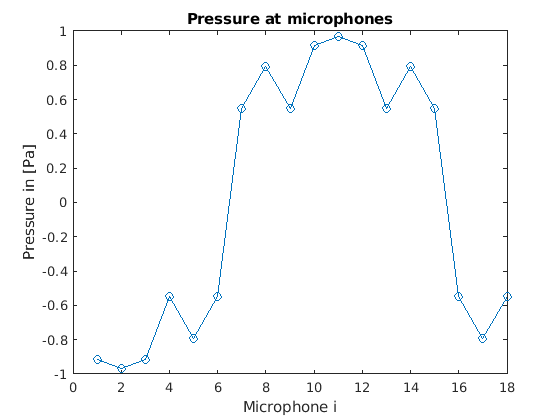

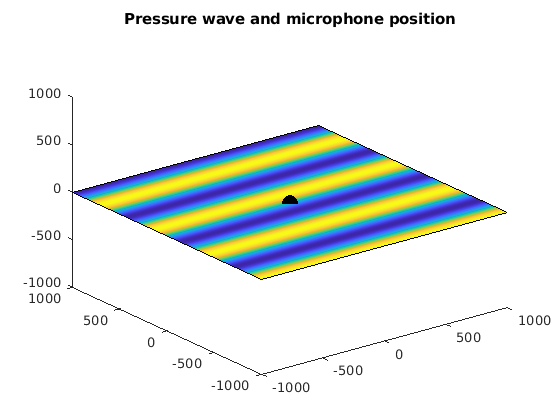

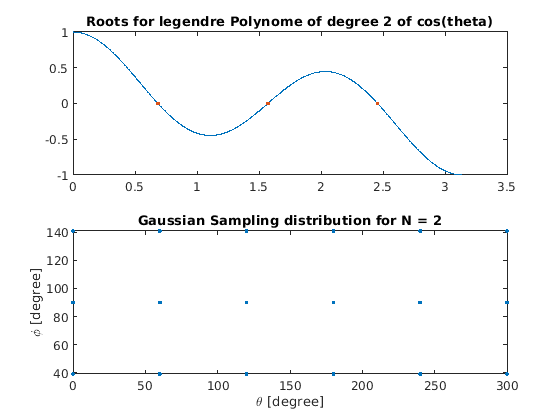

P = harmonics2pressure(Clm,rho_k,r,sz);

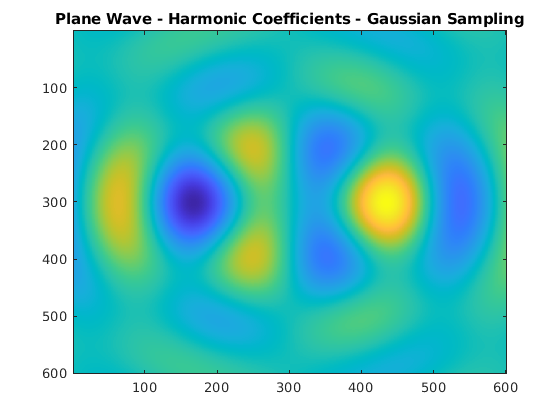

figure;
imagesc(imag(P));
title("Plane Wave - Harmonic Coefficients - Gaussian Sampling");

### Compare

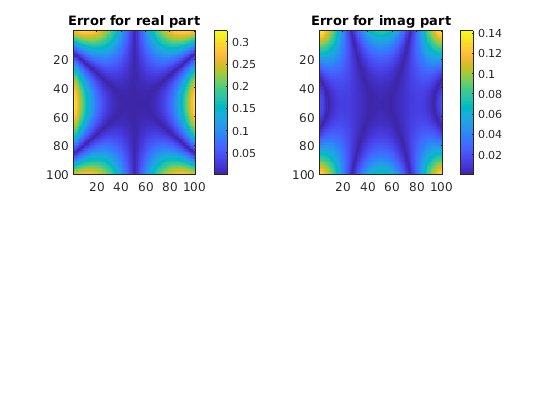

ans = "Max real error:  1.42e-01"

ans = "Max imag error:  3.24e-01"

ans = "Mean error: 5.45e-02"

interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);
cmpWaves(wave(interval1,interval2),P(interval1,interval1),1);

### Mean Error for Values of L

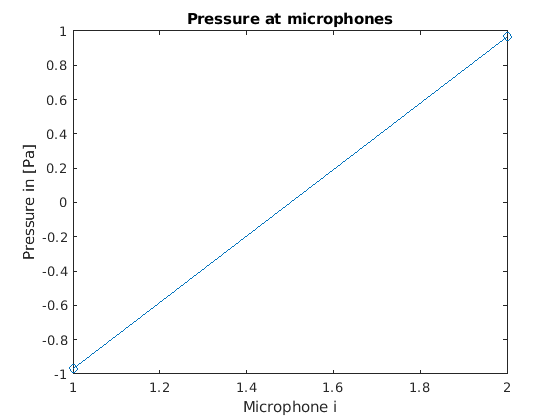

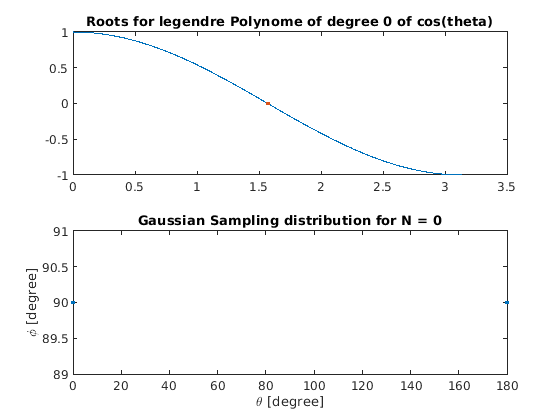

ans = "Max real error:  1.49e+00"

ans = "Max imag error:  1.93e+00"

ans = "Mean error: 8.65e-01"

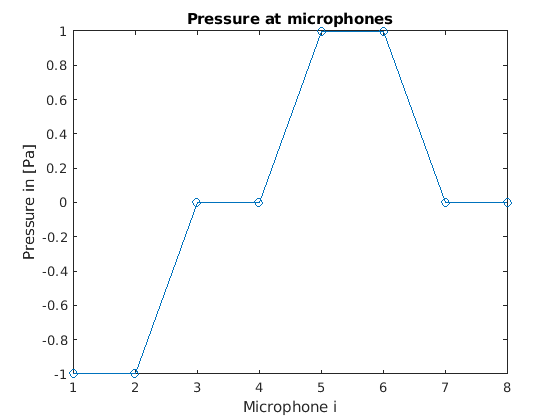

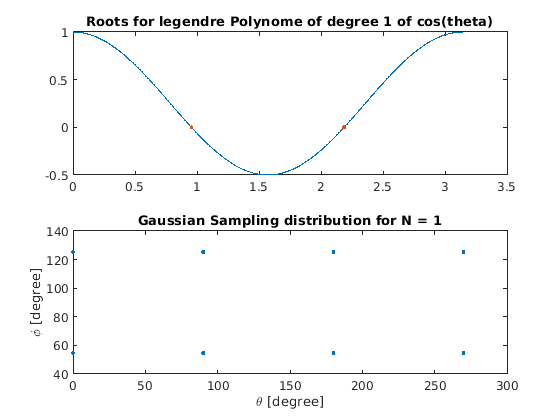

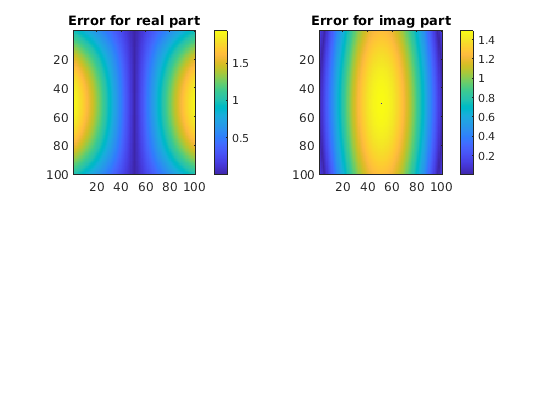

ans = "Max real error:  6.94e-01"

ans = "Max imag error:  2.55e-01"

ans = "Mean error: 1.54e-01"

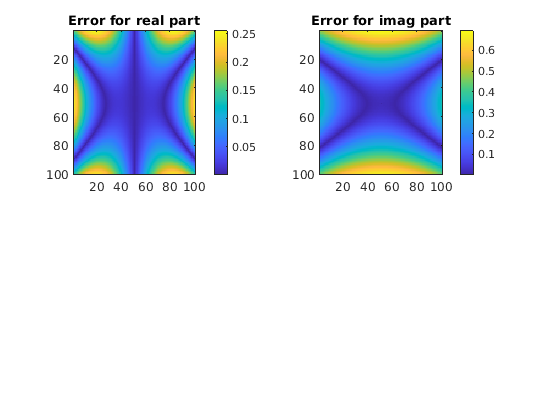

ans = "Max real error:  1.42e-01"

ans = "Max imag error:  3.24e-01"

ans = "Mean error: 5.45e-02"

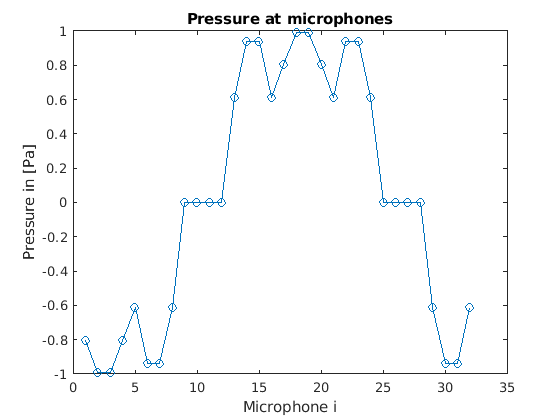

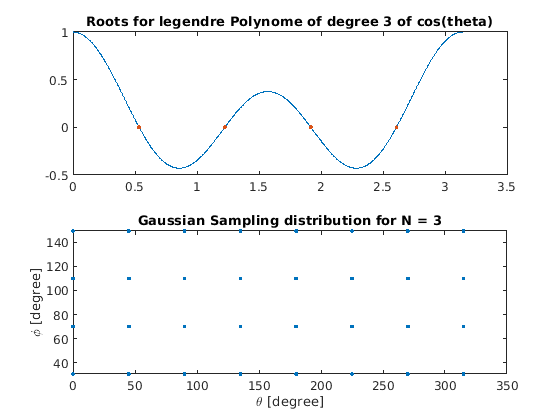

ans = "Max real error:  2.16e-01"

ans = "Max imag error:  1.89e-02"

ans = "Mean error: 1.49e-02"

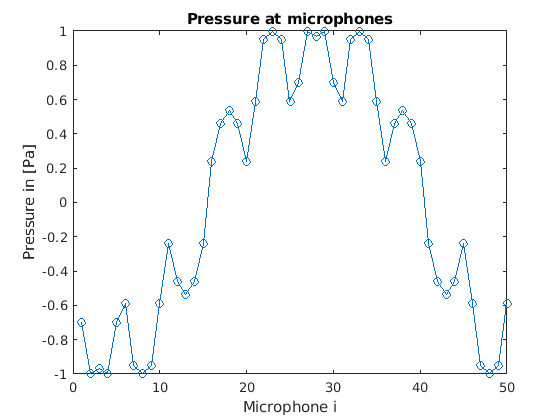

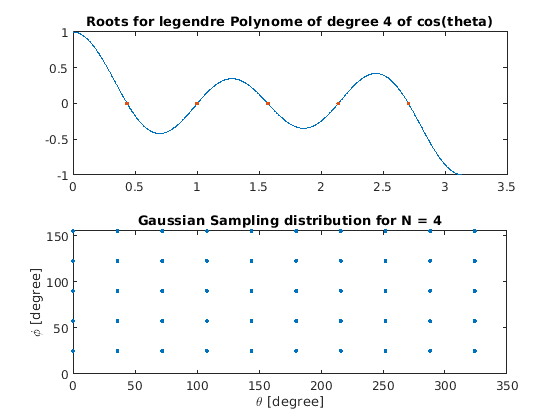

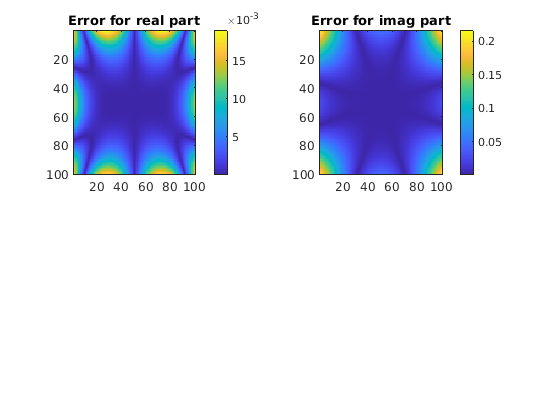

ans = "Max real error:  4.02e-03"

ans = "Max imag error:  2.35e-02"

ans = "Mean error: 1.92e-03"

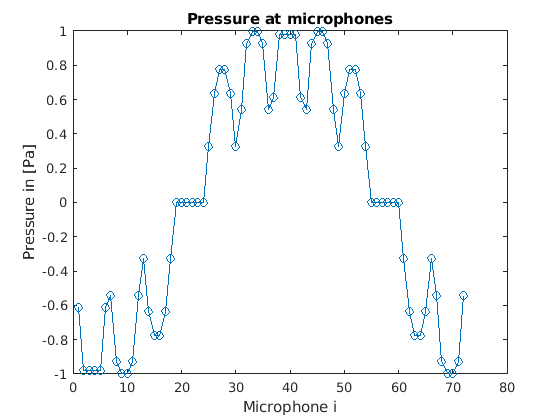

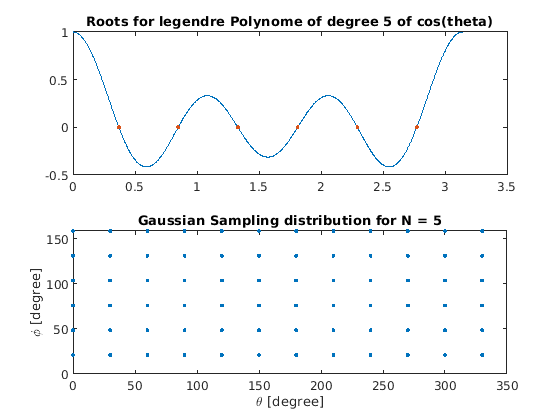

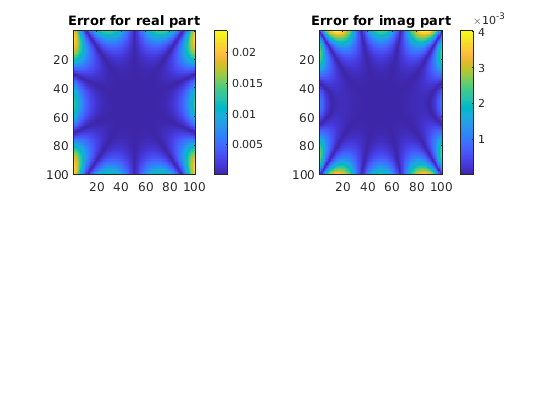

ans = "Max real error:  5.23e-03"

ans = "Max imag error:  1.35e-03"

ans = "Mean error: 3.50e-04"

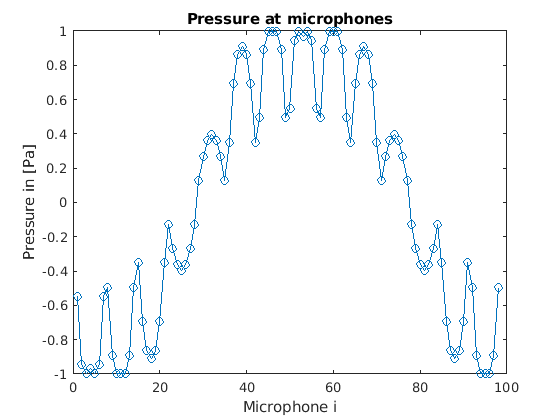

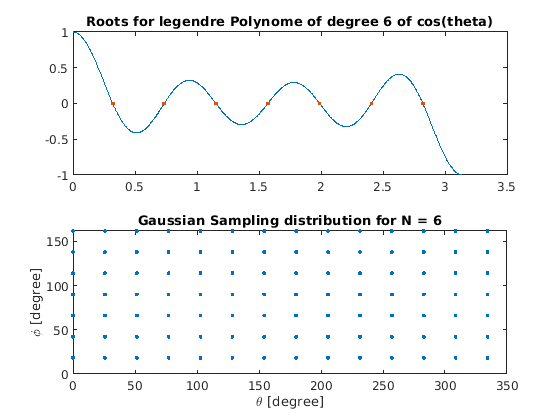

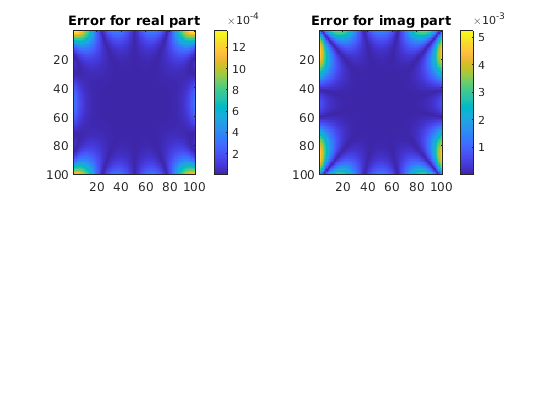

ans = "Max real error:  2.23e-04"

ans = "Max imag error:  1.76e-03"

ans = "Mean error: 5.50e-05"

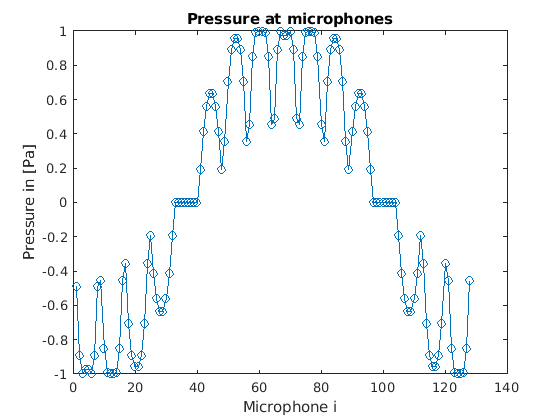

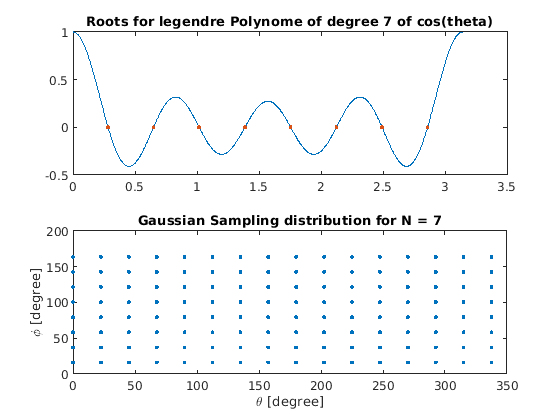

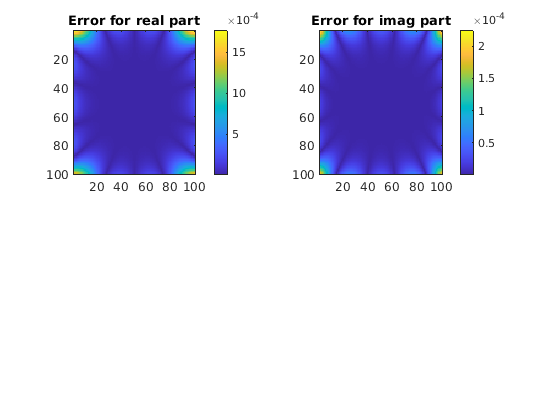

ans = "Max real error:  2.88e-04"

ans = "Max imag error:  2.46e-05"

ans = "Mean error: 6.77e-06"

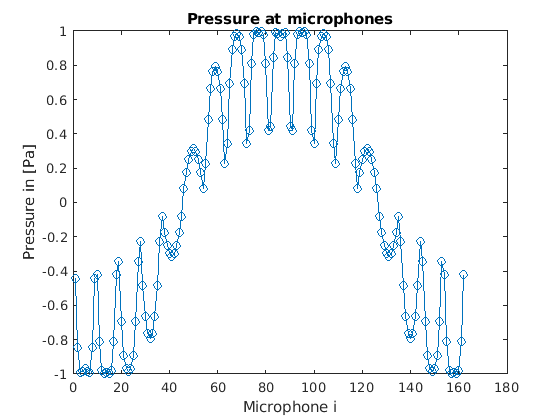

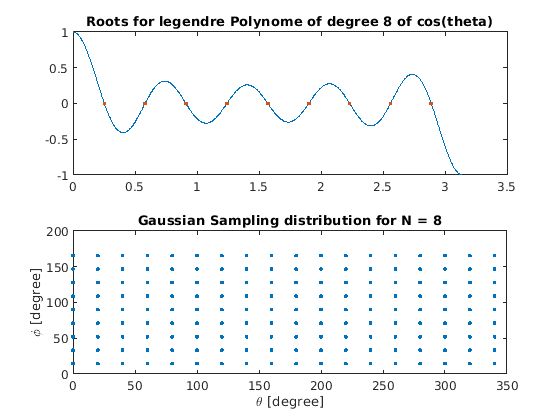

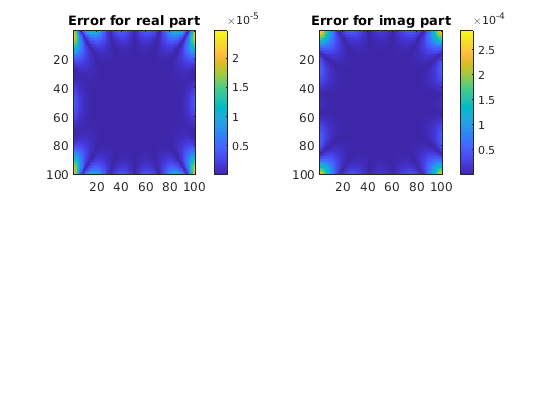

ans = "Max real error:  2.51e-06"

ans = "Max imag error:  3.91e-05"

ans = "Mean error: 8.23e-07"

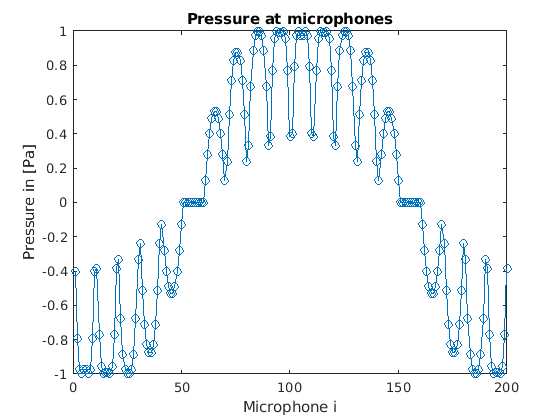

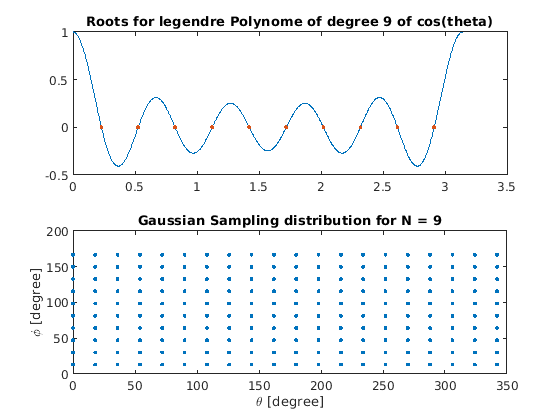

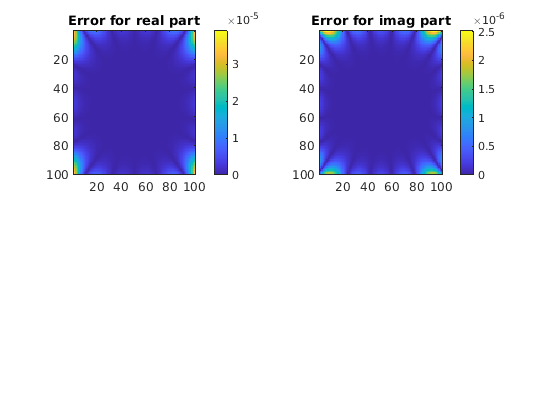

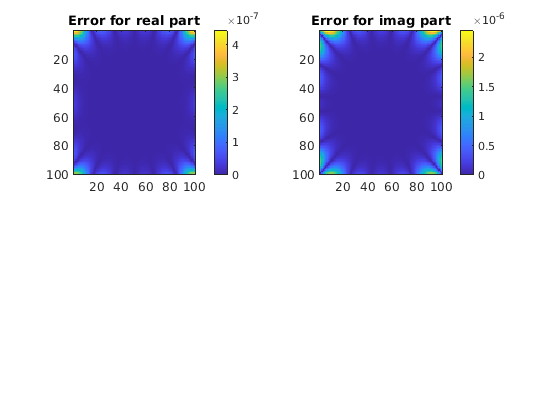

ans = "Max real error:  2.45e-06"

ans = "Max imag error:  4.43e-07"

ans = "Mean error: 6.95e-08"

nL = 10;
meanError = zeros(1,10);
for LL=1:nL
    N = LL-1;
    Clm = harmonicCoefficients(LL,R,rho_k,N,waveFun,n,wave,1);
    P = harmonics2pressure(Clm,rho_k,r,sz);
    interval1 = ceil(sz(1)/2-R/spacing):floor(sz(1)/2+R/spacing);
    interval2 = ceil(sz(2)/2-R/spacing):floor(sz(2)/2+R/spacing);
    meanError(LL) = cmpWaves(wave(interval1,interval2),P(interval1,interval1),0);
end

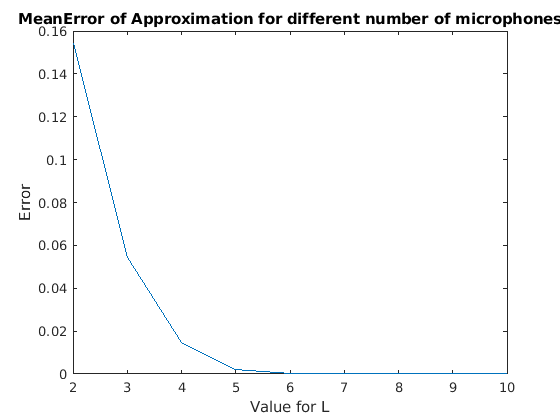

figure;
LL = 2:nL;
plot((LL),meanError(2:nL));
title("MeanError of Approximation for different number of microphones");
xlabel("Value for L");
ylabel("Error");

sprintf("Number of microphones = 2*L^2")

ans = "Number of microphones = 2*L^2"

sprintf("L = 2 -> 8 Microphones")

ans = "L = 2 -> 8 Microphones"

sprintf("L = 3 -> 18 Microphones")

ans = "L = 3 -> 18 Microphones"

sprintf("L = 4 -> 32 Microphones")

ans = "L = 4 -> 32 Microphones"